%1st a)
Ro=2

Ro = 2

b=[1 0]

b =      1     0


a=[1 -Ro]

a =      1    -2


H=tf(b,a,1)

H =
 
    z
  -----
  z - 2
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


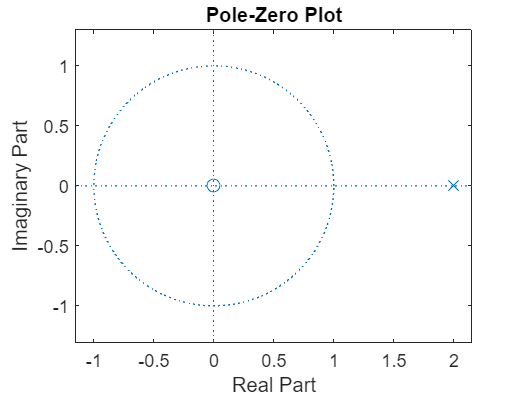

%1st b)
zplane(b,a)

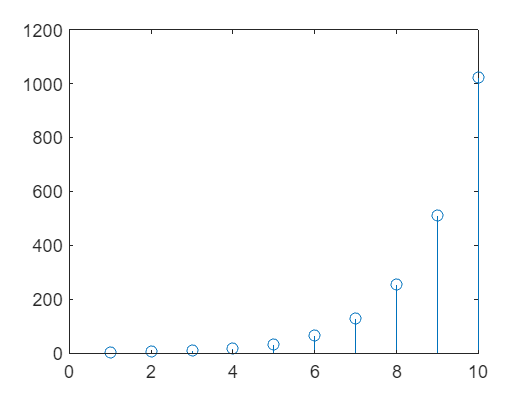

n=[1:10];
y=2.^n;
figure;
stem(n,y)

%1st c)
R01=2.5;
y=1000000;
n=log10(y)/log10(2.5)

n = 15.0776

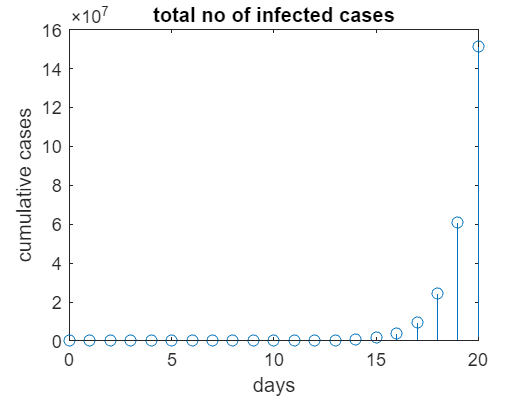

%1st e)
num = [1];
den = [1 -1];
n1 = 0:1:20;
y1 = ((2.5).^n1) .* (n1 >= 0);

% subplot(2,1,1);
% stem(n1, y1);
% 
% subplot(2,1,2);
figure;
H = filter(num, den, y1);
stem(n1, H);
title('total no of infected cases');
xlabel('days')
ylabel('cumulative cases')

%2nd a)
c=[1];
d=[1 -0.1 -0.15 -0.25 -0.26 -0.34 -0.42 -0.25 -0.2 -0.15 -0.1 -0.1 -0.1];
n2=0:1:100;
e=(n2==0);
% subplot(2,1,1)
% stem(e);
% subplot(2,1,2)
h=filter(c,d,e);
plot(h);
title('New daily infections');
xlabel('days')
ylabel('infected population')
%2nd b)
% Define the system
sys = tf(c, d, 1);
n=1:100;
% Define the input Kronecker delta
input_signal = [1, zeros(1, 100)]; % Adjust the length as needed

% Simulate the system
output_signal = lsim(sys, input_signal);
integrator=filter(1, [1 -1],output_signal);
% Find the day when output reaches 1,000,000
output_threshold = 1e6;
day_of_interest = find(integrator >= output_threshold, 1)-1

%3rd
c=[1];
rho = [0.25 0.50 0.75];
for i=rho
ak=(1-i).*[-0.1 -0.15 -0.25 -0.26 -0.34 -0.42 -0.25 -0.2 -0.15 -0.1 -0.1 -0.1];

sys = tf(c,[1 ak], 1);
n=0:1:100;
% Define the input Kronecker delta
input_signal = (n==0); % Adjust the length as needed

% Simulate the system
output_signal = lsim(sys, input_signal);
integrator_1=filter(1, [1 -1],output_signal);
output_threshold = 1e6;
%day_of_interest = find(integrator_1 >= output_threshold, 1)-1;
total_no_of_infections=integrator_1(end)
figure;
plot(n,output_signal)
title(['New daily infections when \rho = ', num2str(i)])
xlabel('days')
ylabel('infected population')
end

% Problem 4

% Part(1)
Ro = 1.15;
K = 10^6;
n = 1:100;

logistic = (K./(1+(K*(Ro-1) - Ro)*Ro.^(-n-1))) - (1/(Ro-1));
Integrator3 = filter(1,[1 -1],logistic);
Total_infections2 = Integrator3(end) % Total infections in 100 days

days = 0:100;
Ro = 1.15;
populationx = [0];
for i = days
    populationx(days == i) = Ro^i;
end
figure;
plot(n,logistic)
hold on 
plot(days,populationx)
hold off
title("New Daily Infections")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on
legend("Logistic","First-order model")


% Part(2)
filter_1 = filter([1 -1],1,logistic); % First derivative
filter_2 = filter([1 -2 1],1,logistic); % Second derivative 

Global_maximum = max(filter_1) % Global max value
Value_n = n(filter_1 == max(filter_1)) % Days corresponding to max value
Zero_crossing = n(round(filter_2) == 94) % Inflection point

figure;
plot(n,filter_1,n(Value_n),filter_1(Value_n),'ro')
title("First derivative")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on

figure;
plot(n,filter_2,n(Zero_crossing),filter_2(Zero_crossing),'ro')
title("Second derivative ")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on
